3 задание

Lx = linspace(-pi,pi,40);
Ly = linspace(-pi, pi, 50);

[X,Y] = meshgrid(Lx,Ly);
Z = F(X,Y);
surfc(X,Y,Z)
xlabel ('x');
ylabel ('y');
zlabel ('z');
hold on

продолжение 3его задания

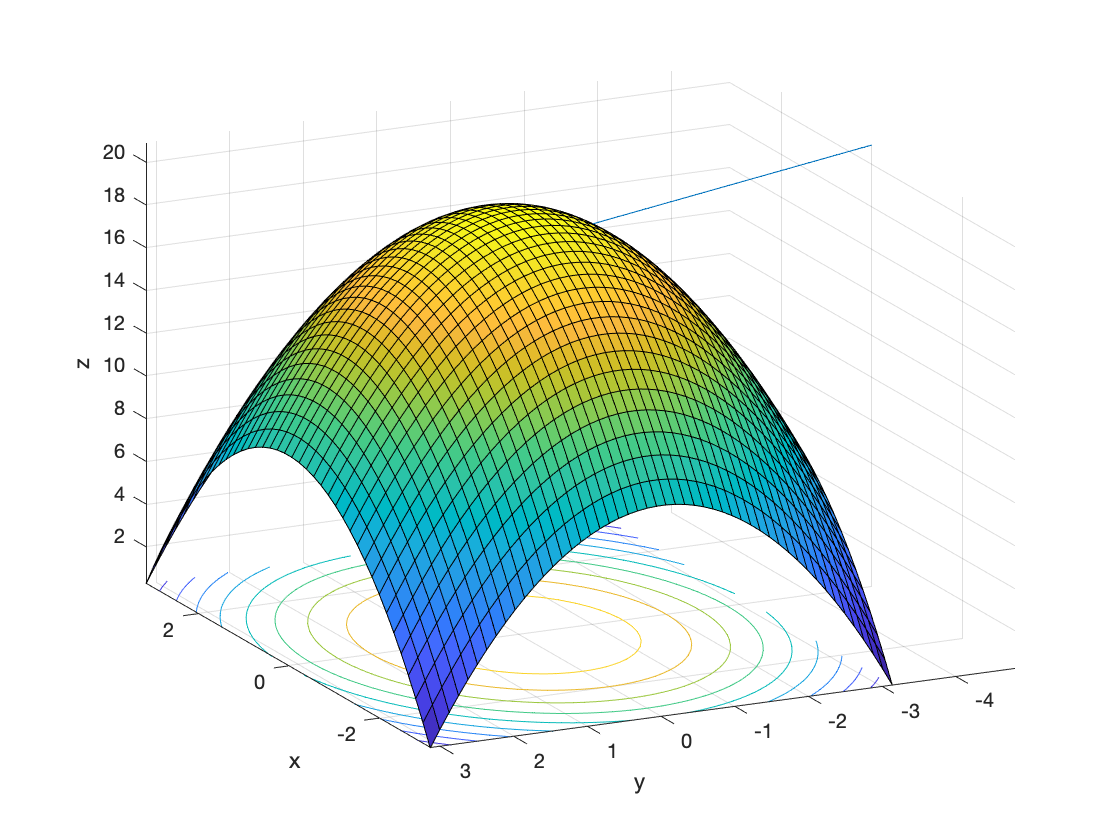

x0 = 0;
y0 = -1;
z0 = F(x0,y0);
h = 0.001;
t = z0:0.01:1.1*z0;
Fx = (F(x0+h,y0)-F(x0,y0))/h;
Fy = (F(x0,y0+h)-F(x0,y0))/h;
Nx = x0-(Fx.*(t-z0));
Ny = y0-(Fy.*(t-z0));
Nz = t;
plot3(Nx, Ny, Nz);